Internal delays can arise when we add a feedback loop to a system with an I/O delay (at the input or output), as shown here [https://www.mathworks.com/help/control/ug/closing-feedback-loops-with-time-delays.html](https://www.mathworks.com/help/control/ug/closing-feedback-loops-with-time-delays.html) :

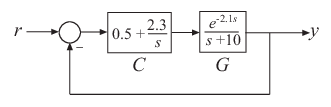

G = tf(1,[1 10], 'InputDelay' ,2.1);
C = pid(0,5,2,3);
T = feedback(C*G,1);
[H,tau] = getDelayModel(T);
H


H =
 
  A = 
           x1      x2      x3
   x1  -10.33  -1.667       0
   x2       2       0       0
   x3       0     0.5       0
 
  B = 
        ?  w1
   x1   0   2
   x2   0   0
   x3   0   0
 
  C = 
            x1       x2       x3
   ?    0.3333     1.25   0.8333
   z1  -0.3333    -1.25  -0.8333
 
  D = 
        ?  w1
   ?    0   0
   z1   1   0
 
Continuous-time state-space model.


tau

tau = 2.1000

## `delayss()`

It is used to create time-delay systems described by the form (it is a combination of systems with input, output, and internal delays):

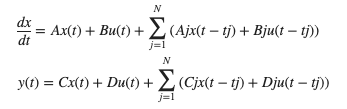

One should define a matrix with $j$ rows and elements for the delay (in seconds), and corresponding elements for matrices A, B, C, D.

**NOTE**! During the display of matrices A, B, C, D, the software sets all delays to zero (creating a zero-order Padé approximation). This approximation occurs only for display purposes, not for calculations using the model. If the display returns an error or only the size, it means that setting the delay to zero caused the system to fall into an algebraic loop.

clear all;
close all;

DelayT(1) = struct('delay',0.5,'a',0,'b',2,'c',1,'d',0);
DelayT(2) = struct('delay',1.2,'a',-1,'b',0,'c',0,'d',0);
sys = delayss(1,0,0,1,DelayT) 


sys =
 
  A = 
       x1
   x1   0
 
  B = 
       u1
   x1   2
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   1
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 0.5  0.5  1.2 
 
Continuous-time state-space model.


What can we do?

Acording [https://www.mathworks.com/help/control/ug/internal-delays.html](https://www.mathworks.com/help/control/ug/internal-delays.html) systems with internal delay are supported withflowoing functions:

-  generating time and frequency domain responses in countinous time (pade approximation is not needed)

- `margin, allmargin, pole, zero, get, ssdata `but with some constrains (look part 2.)

Thay are NOT supported with (untill not approximated) :  `norm, isstable, initial, initialplot, balreal, balred, modred, rlocus, lqg, lqry, lqrd, kalman, kalmd, lqgreg, lqi, augstate`

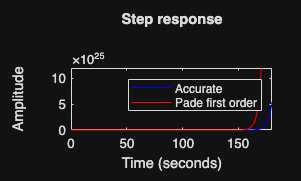

% part 1.
sys1 = pade(sys,1); 
step(sys, "b", sys1, "r") %and other time-domain response functions beyond impulse and initial
title("Step response")
legend( 'Accurate' , 'Pade first order' )

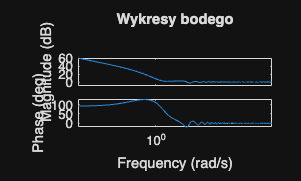


% impulse(sys)
% title("Impulse response") NOT SUPPORTED
% initial(sys)
% title("Unforced (natural) response") NOT SUPPORTED

bode(sys) % and other frequency domain response functions beyond the norm
title("Wykresy bodego")


% norm(sys) 
% title("mean square impulse response") NOT SUPPORTED

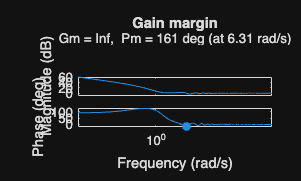

% part 2.
% THEY USE INTERPOLATION
margin(sys)
title("Gain margin")


allmargin(sys)

ans = struct with fields:
     GainMargin: [1×0 double]
    GMFrequency: [1×0 double]
    PhaseMargin: [160.7247 -168.9122 170.6449 -172.9823 174.1973 -174.6069 175.8122 -175.8503 176.3788 -176.8717 176.9370 -177.3159 177.4096 -177.5933 177.7476 -177.8183 178.0425 -178.1805 178.2185 -178.3214 178.3194 -178.5102 178.4879 … ] (1×50 double)
    PMFrequency: [6.3064 9.2416 12.5087 15.6522 18.8105 21.9193 25.1450 28.1750 31.4486 34.4802 37.7031 40.7994 43.9639 47.1029 50.2494 53.3756 56.5572 59.6393 62.8444 65.9283 69.1196 72.2266 75.3902 78.5353 81.6712 84.8100 87.9628 … ] (1×50 double)
    DelayMargin: [0.4448 0.3609 0.2381 0.2085 0.1616 0.1476 0.1220 0.1141 0.0979 0.0927 0.0819 0.0781 0.0704 0.0676 0.0617 0.0596 0.0549 0.0532 0.0495 0.0481 0.0450 0.0439 0.0413 0.0403 0.0382 0.0373 0.0355 0.0347 0.0331 0.0325 0.0311 … ] (1×50 double)
    DMFrequency: [6.3064 9.2416 12.5087 15.6522 18.8105 21.9193 25.1450 28.1750 31.4486 34.4802 37.7031 40.7994 43.9639 47.1029 50.2494 53.3756 56.5572 59.63

disp('Gain, Phase and Delay Margin');

Gain, Phase and Delay Margin



% SET DELAYS TO ZERO
pole(sys)

ans = 0

disp("Systems pools")

Systems pools


zero(sys)

ans = -2

disp("Systems zeros")

Systems zeros


ssdata(sys)

ans = 0

disp("State space matrixes")

State space matrixes


get(sys)

                A: 0
                B: 2.0000
                C: 1
                D: 1
                E: []
          Offsets: []
           Scaled: 0
        StateName: {''}
        StatePath: {''}
        StateUnit: {''}
    InternalDelay: [3×1 double]
       InputDelay: 0
      OutputDelay: 0
        InputName: {''}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]



disp("System information")

System information


## Time delay model, `getDelayModel()`

is represented by

- normal state space H(s) with extended inputs,

- set of internal delays.

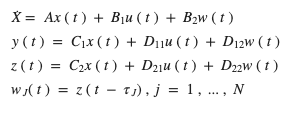                                      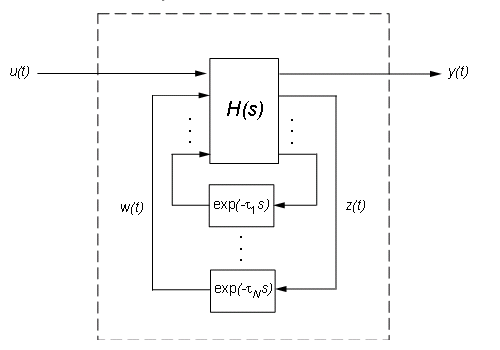

To obtain a time delay model in the form of a state space model without delays and a delay vector, the function `getDelayModel() `(inverse function is `setDelayModel()`)

sys


sys =
 
  A = 
       x1
   x1   0
 
  B = 
       u1
   x1   2
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   1
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 0.5  0.5  1.2 
 
Continuous-time state-space model.


[H, tau] = getDelayModel(sys) % for ss, sprass, mechss types


H =
 
  A = 
       x1
   x1   1
 
  B = 
           ?     w1     w2     w3
   x1      0  1.414      0      1
 
  C = 
       x1
   ?    0
   z1   0
   z2  -1
   z3  -1
 
  D = 
           ?     w1     w2     w3
   ?       1      0     -1      0
   z1  1.414      0      0      0
   z2      0      0      0      0
   z3      0      0      0      0
 
Continuous-time state-space model.


tau =     0.5000
    0.5000
    1.2000


## System with delay analysis

[https://www.mathworks.com/help/control/ug/analyzing-control-systems-with-delays.html](https://www.mathworks.com/help/control/ug/analyzing-control-systems-with-delays.html)

- time and frequency domain responses

- pade approximation

- sensitivity analysis

- discretization 

% tu dodać kod kiedyś

## Interesting features of systems with delays

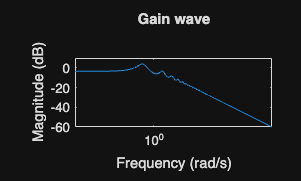

s = tf('s'); 
G = exp(-5*s)/(s+1);
T = feedback(G,.5);
bodemag(T)
title("Gain wave")

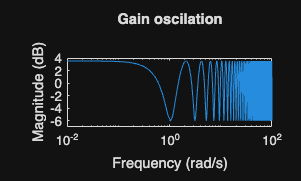


G = 1 + 0.5 * exp(-3*s);
bodemag(G)
title("Gain oscilation")

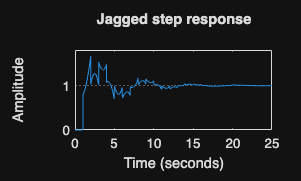


G = exp(-s) * (0.8*s^2+s+2)/(s^2+s);
T = feedback(G,1);
step(T)
title("Jagged step response")

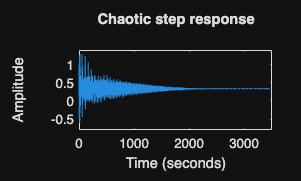


G = 1/(s+1) + exp(-4*s);
T = feedback(1,G);
step(T)
title("Chaotic step response")

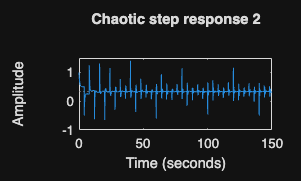


G = 1/(s+1) + exp(-4*s);
T = feedback(1,G);
stepplot(T,150)
title("Chaotic step response 2")